Consider the confound of age.

Mean: ratio of age mean between sites

Variance: ratio of age variance between sites

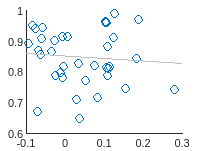

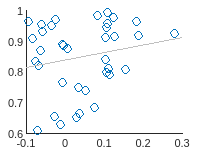

BD


                       Mean       Variance
                     _________    ________

    spearman corr    -0.064093    0.18507 
    p                  0.38121    0.13481 



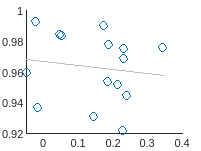

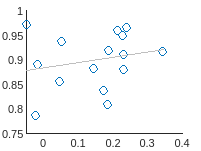

SCA


                       Mean      Variance
                     ________    ________

    spearman corr    -0.23571    0.24643 
    p                 0.25176    0.21779 



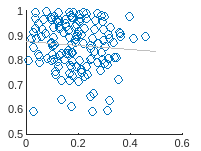

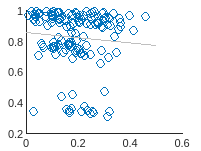

SCZ


                       Mean       Variance
                     _________    ________

    spearman corr    -0.093049    -0.15287
    p                  0.25649     0.18335



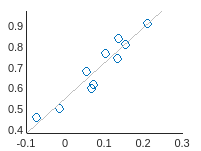

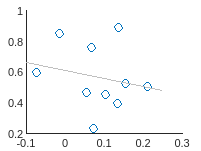

ASD


                       Mean       Variance
                     _________    ________

    spearman corr      0.93939    -0.15152
    p                0.0072469     0.34721



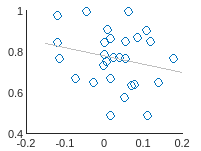

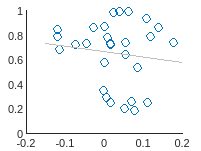

MDD


                       Mean      Variance
                     ________    ________

    spearman corr    -0.16913    -0.05364
    p                 0.21976     0.41051



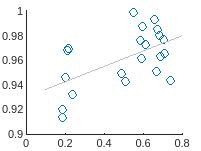

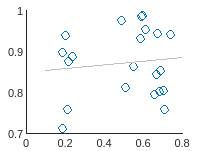

AD


                       Mean      Variance 
                     ________    _________

    spearman corr     0.42468    -0.020779
    p                0.054611      0.48976



% Clear all variables and close all figures
clear all
close all

% Initialize parameters
iCOMBAT = 1; % Flag to determine if COMBAT harmonization is used
smoothKernel = 6; % Smoothing kernel size
iter = 5000; % Number of iterations for permutation testing
type = 'spearman'; % Correlation type (Spearman)
diagnosisString = {'BD', 'SCA', 'SCZ', 'ASD', 'MDD', 'AD'}; % List of diagnoses to analyze

nDiag = length(diagnosisString); % Number of diagnoses

% Set the address path based on whether COMBAT harmonization is applied
if iCOMBAT == 1
    address = ['derivatives/s', num2str(smoothKernel), 'COMBAT/'];
else
    address = ['derivatives/s', num2str(smoothKernel), '/'];
end

% Load metadata about demographics and site information
metadata = readtable(['/projects/kg98/trangc/VBM/data/metadataVBM_extended.csv']);
% Load pre-computed correlation matrices and site lists
load(['output/corr_tmap_combat',num2str(iCOMBAT),'_smooth',num2str(smoothKernel),'.mat'], 'cor1', 'cor2',"siteList")

% Loop through each diagnosis
for iDiag = 1:nDiag
    % Compute variance related to age and site correlation
    [varTable{iDiag} nSite{iDiag}]= cor_var_age(metadata, ...
        diagnosisString(iDiag), cor1{iDiag}, cor2{iDiag}, siteList{iDiag},iter, type);

 % Display results if the variance table is not empty
    if size(varTable,1)~=0
        disp(char(diagnosisString(iDiag))); % Display diagnosis name
        disp(varTable{iDiag}); % Display variance table
        disp(' '); % Add spacing
        disp(' ')
    end
end


% Suppress specific warnings and save the results

warning('off','last')

Error using warning
The last warning issued had an empty warning identifier, or no warnings have yet been issued.

save('output/confound_age.mat','varTable','nSite')